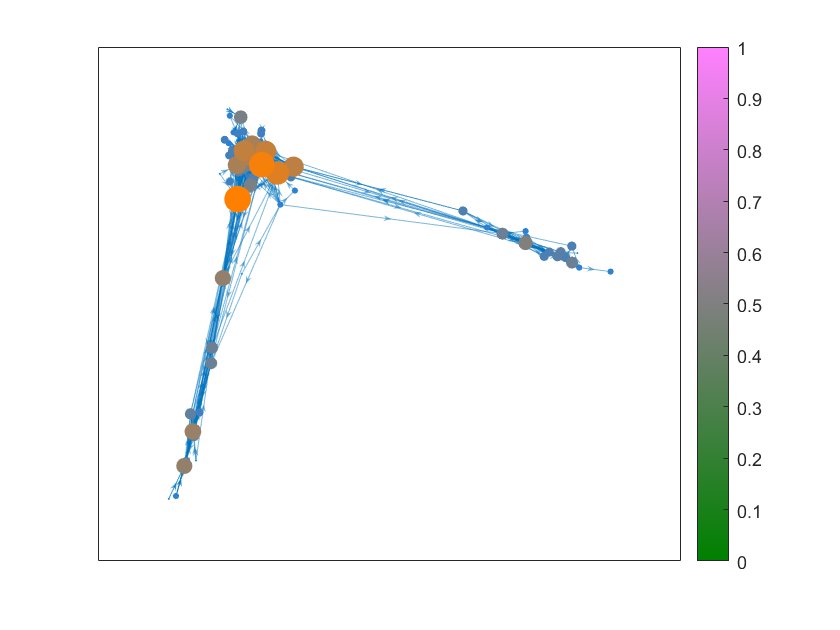

inp = readtable("g_edges.csv");
all_names = [inp.Source; inp.Target];
all_names = unique(all_names);

s_1 = inp.Source'; s_1 = string(s_1);
t_2 = inp.Target'; t_2 = string(t_2);
matr = zeros(length(all_names));

uni_num = containers.Map(all_names,1:length(all_names));
for i=1:length(t_2)
    matr(uni_num(s_1(i)),uni_num(t_2(i))) = matr(uni_num(s_1(i)),uni_num(t_2(i)))+1;
end

deg_gr = sum(matr);
size_v = 2*sqrt(deg_gr-min(deg_gr))+0.2;
col = size_v/max(size_v)';
colour = ([col;0.5*ones(1,length(deg_gr));1-col]);

s_graph = zeros(1,length(s_1));
t_graph = zeros(1,length(t_2));
for i = 1:length(s_1)
    s_graph(i) = uni_num(s_1(i));
    t_graph(i) = uni_num(t_2(i));
end

Graph = digraph(s_graph,t_graph,(double(inp.Weight))');
plot(Graph,'MarkerSize',size_v,'NodeColor',colour');
xlim([-2.48 5.69]);
ylim([-5.52 2.28]);
colormap([linspace(0,1,256);0.5*ones(1,256);linspace(0,1,256)]');
colorbar;


top = sort(deg_gr,'descend');
top_lim = top(6);
disp(all_names(deg_gr>top_lim));

    {'NED'   }
    {'ROBB'  }
    {'ROBERT'}
    {'SANSA' }
    {'TYRION'}




for i=shortestpath(Graph,uni_num("NED"),uni_num("TYRION"))
    disp(all_names(i))
end

    {'NED'}

    {'PYP'}

    {'TYRION'}

